
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% initialize combined output variables
            
%


            ll = 1;
            mm = 1;
            nn = 1;
            oo = 1;
            pp = 1;
            qq = 1;
            rr = 1;
            ss = 1;
            tt = 1;
            uu = 1;
            
         
            combined_binned_ramp = NaN(10,200);
        
       
            aaa = 1;
            bbb = 1;
            ccc = 1;
            ddd = 1;
            eee = 1;
            fff = 1;
            ggg = 1;
            hhh = 1;
            jjj = 1;
            kkk = 1;

            count = 0;
            nocount = 0;
            
%}
      




# filter, baselined, measure the delta Vm in the initial and final stages of the response.

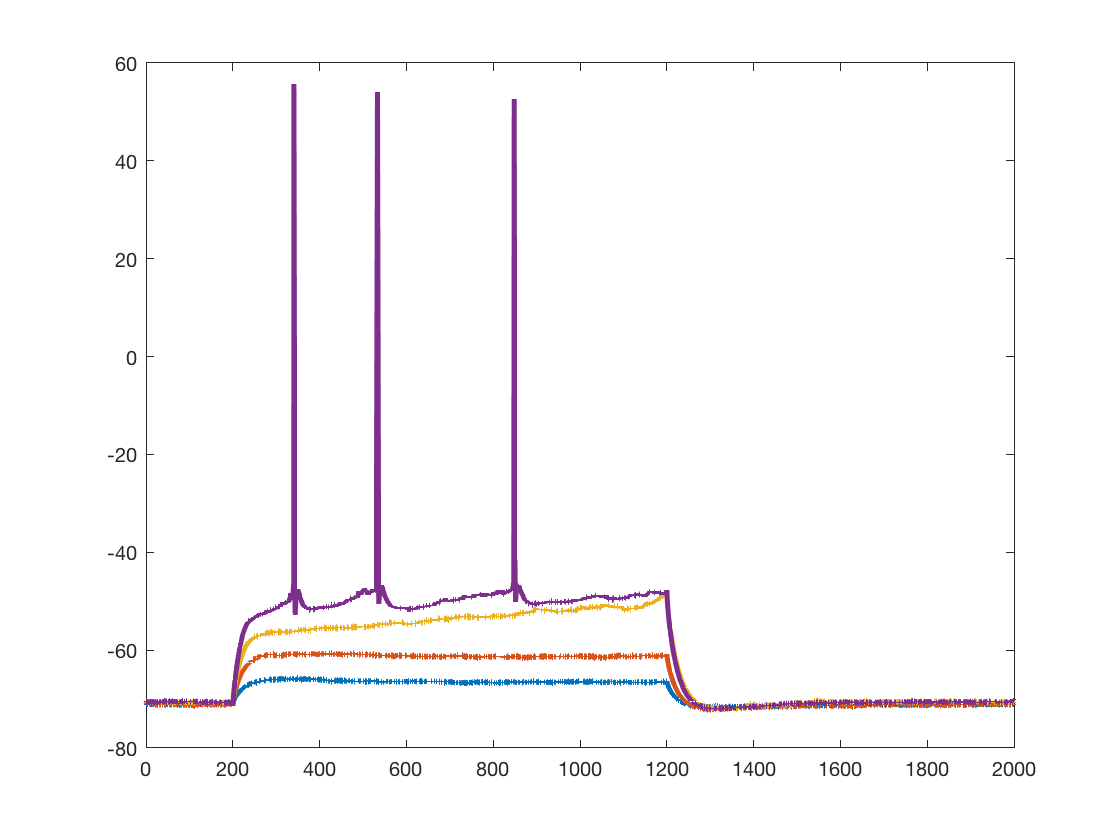

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

 
t = c001_Time*1000;

in = [c002_Membrane_Voltage_1; c003_Membrane_Voltage_1; c004_Membrane_Voltage_1; c005_Membrane_Voltage_1; c006_Membrane_Voltage_1; c007_Membrane_Voltage_1; c008_Membrane_Voltage_1; c009_Membrane_Voltage_1; c010_Membrane_Voltage_1; c011_Membrane_Voltage_1]*1000;
%in = [c002_Membrane_Voltage_2; c003_Membrane_Voltage_2; c004_Membrane_Voltage_2; c005_Membrane_Voltage_2; c006_Membrane_Voltage_2; c007_Membrane_Voltage_2; c008_Membrane_Voltage_2; c009_Membrane_Voltage_2; c010_Membrane_Voltage_2; c011_Membrane_Voltage_2]*1000;

clear c002_Membrane_Voltage_1 c003_Membrane_Voltage_1 c004_Membrane_Voltage_1 c005_Membrane_Voltage_1 c006_Membrane_Voltage_1 c007_Membrane_Voltage_1 c008_Membrane_Voltage_1 c009_Membrane_Voltage_1 c010_Membrane_Voltage_1 c011_Membrane_Voltage_1
%clear c002_Membrane_Voltage_2 c003_Membrane_Voltage_2 c004_Membrane_Voltage_2 c005_Membrane_Voltage_2 c006_Membrane_Voltage_2 c007_Membrane_Voltage_2 c008_Membrane_Voltage_2 c009_Membrane_Voltage_2 c010_Membrane_Voltage_2 c011_Membrane_Voltage_2
clear c001_Time

figure;
plot(t,in(1:4,:),'LineWidth',2.5);

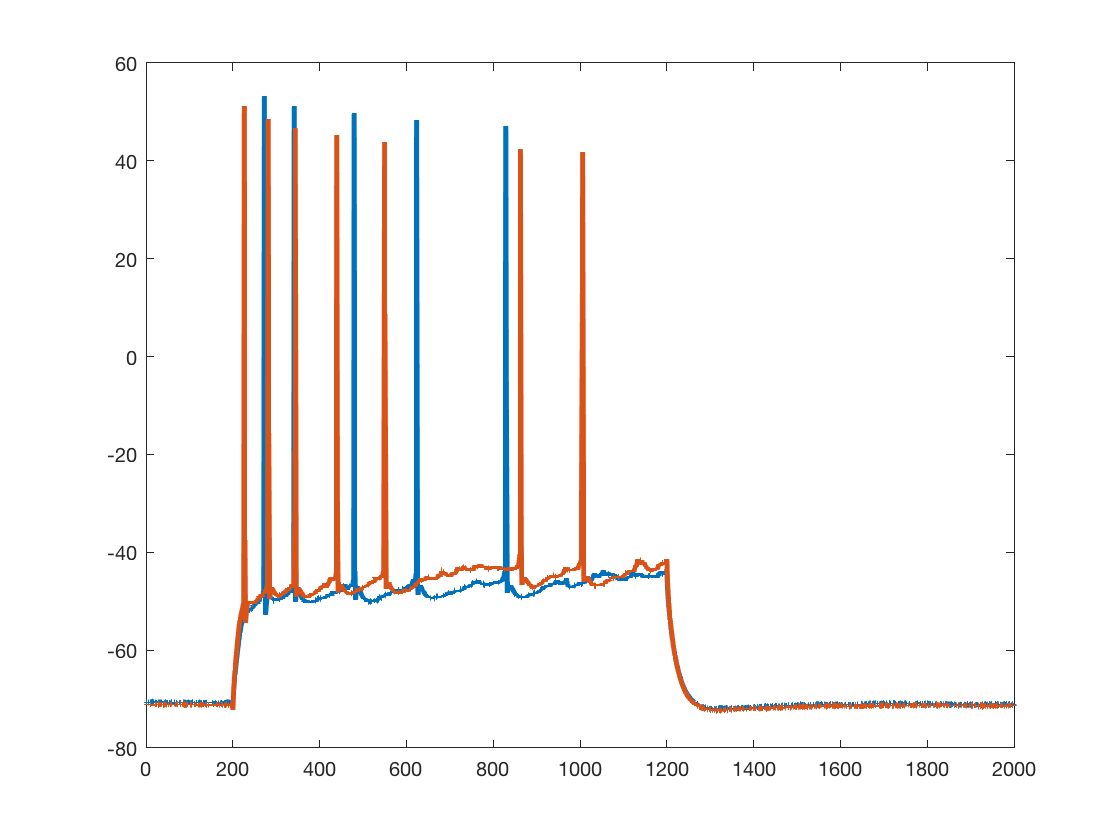

%xlim([150 250]);
%ylim([-80 -60]);
figure;
plot(t,in(5:6,:),'LineWidth',2.5);

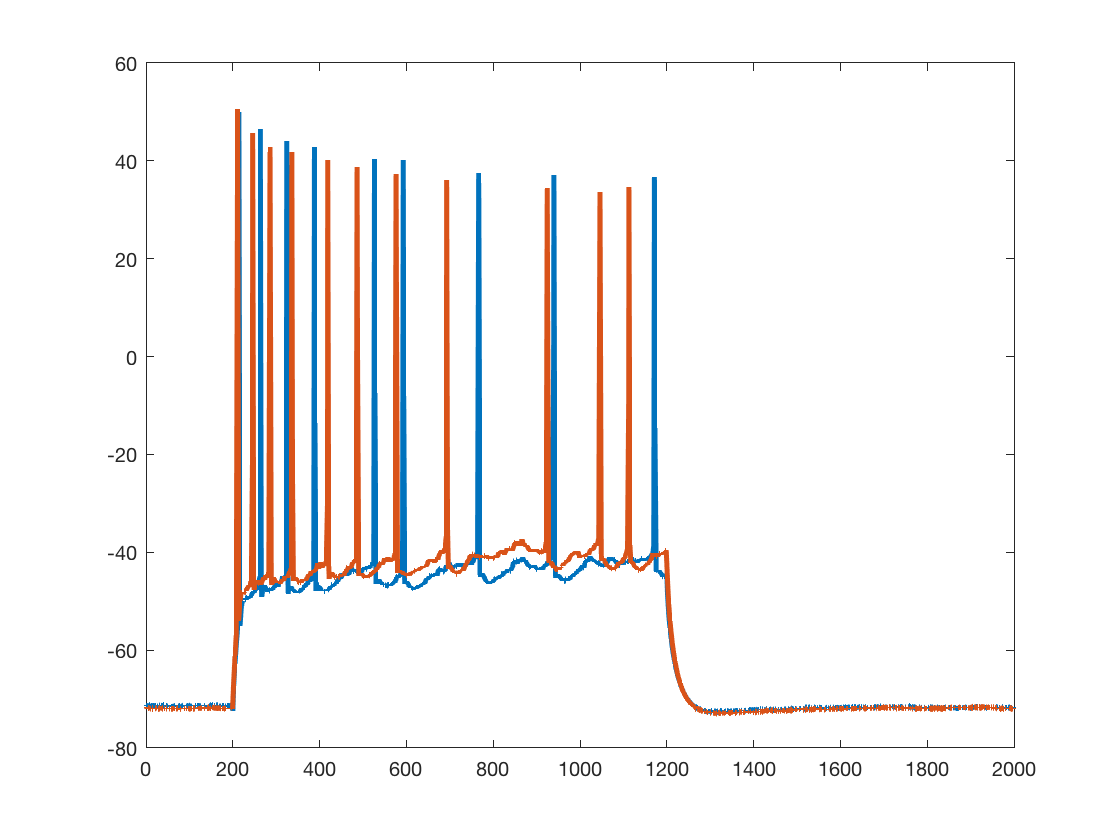

figure;
plot(t,in(7:8,:),'LineWidth',2.5);

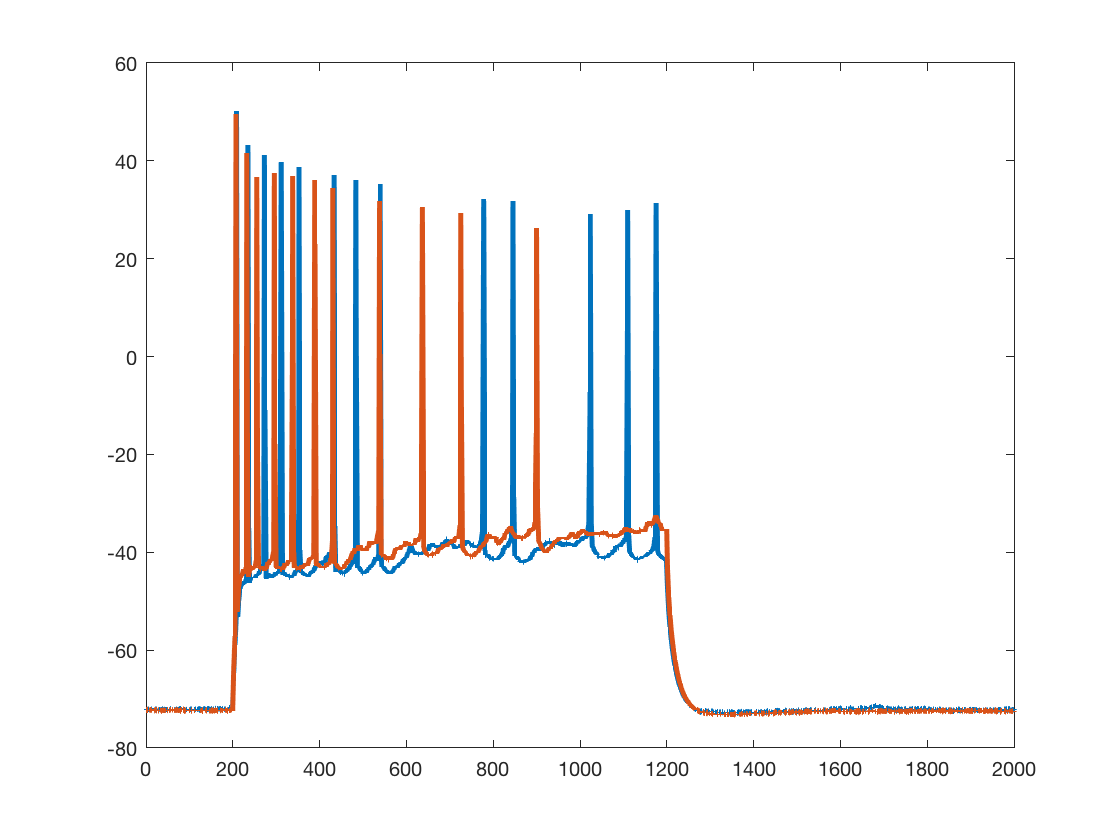

figure;
plot(t,in(9:10,:),'LineWidth',2.5);





% baseline sweeps 



for k = 1:10
    baseline(k) = mean(in(k,3400:4000));
end

a = baseline';

in_baselined = in - a;






## Measure initial Vm, final Vm, and slow delta Vm




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


r = 1;

h = 5;   % this is the interval used by diff 

%figure;
%plot(t,in_baselined);

t_step = t(4000:h:24000);

Vstep_line_early = zeros(10,40000);
Vstep_line_late = zeros(10,40000);


for r = 1:10;

    step = in(r,4000:h:24000);
   % figure;
   % plot(t_step,step);
    
    
    k = 1;
    for k=1:1;
        in_d = diff(step(k,:))*20;
        in_d(k,end+1) = 0;
        k = k+1;
    end
    
  
   % figure
   % plot(t_step,in_d)
   % hold on
   % plot(t,in_baselined(r,:))
    
  
    b = 1;
                 
    q = (150-(r*10));
    while q < (501 - (r*35)) 
    if in_d(q) < 0.2 & in_d(q) > -0.2; 
        Vstep_early(b) = step(q);                                        
        q = q+1;
        b = b+1;
    else
        Vstep_early(b) = NaN;
        q = q+1;
        b = b+1;
    end
    end
        
        
        
    Vstep_all_early(r) = nanmean(Vstep_early);
    
    Vstep_line_early(r,:) = Vstep_all_early(r);
    
    clear Vstep_early
    clear q
    clear b 
    
    
    j = 3700;
    w = 1;
    while j < 4001 
        if in_d(j) < 10 & in_d(j) > -10; 
            Vstep_late(w) = step(j);                                        
            j = j+1;
            w = w+1;
        else
            Vstep_late(w) = NaN;
            j = j+1;
            w = w+1;
        end
    end
    
    Vstep_all_late(r) = nanmean(Vstep_late);
    
    
    Vstep_line_late(r,:) = Vstep_all_late(r);
    
    clear Vstep_late
    clear j
    clear w
    
end

x = Vstep_all_early'

x =   -66.2577
  -61.4667
  -57.0013
  -53.1049
  -50.5641
  -49.9730
  -49.2264
  -47.5819
  -45.7447
  -44.3993


y = Vstep_all_late'

y =   -66.5245
  -61.2135
  -50.2768
  -48.4818
  -44.6821
  -42.7314
  -42.3932
  -41.7295
  -40.3232
  -34.7950




y_baselined = y - a;
y_baselined

y_baselined =     4.4513
    9.8651
   20.4107
   22.1779
   26.0840
   28.4645
   29.0132
   30.1503
   31.6300
   37.4862


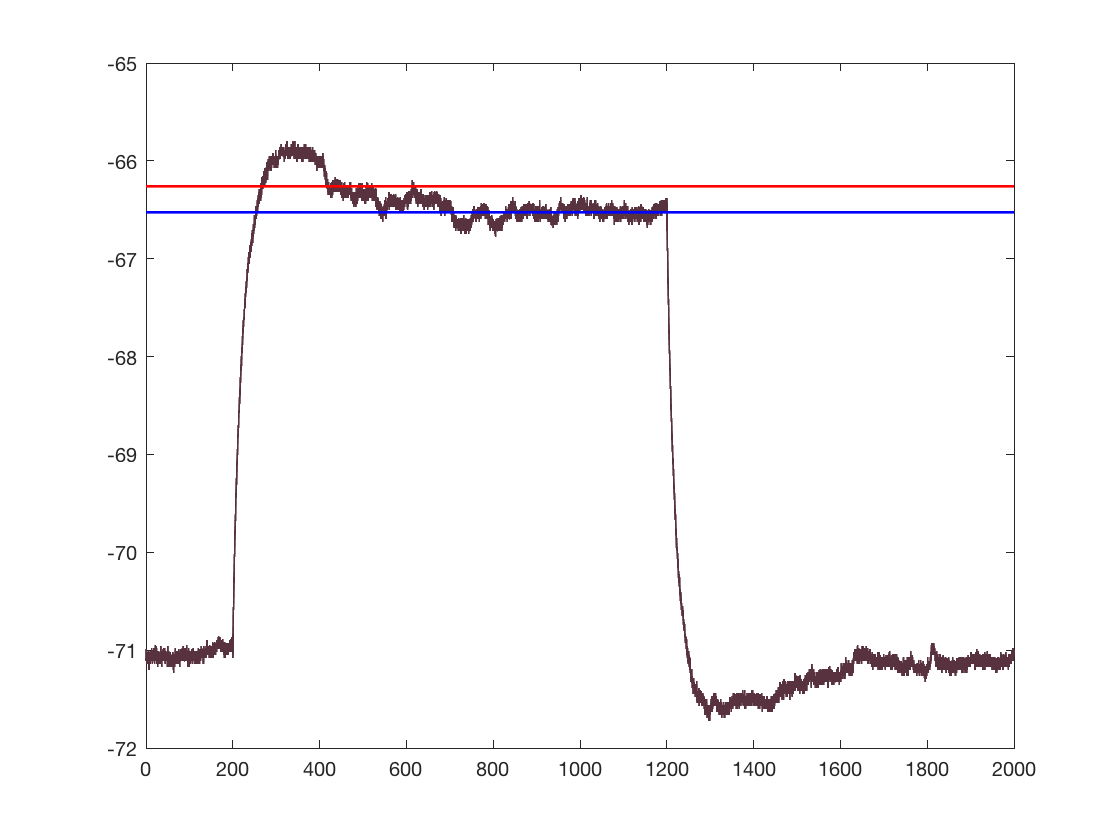

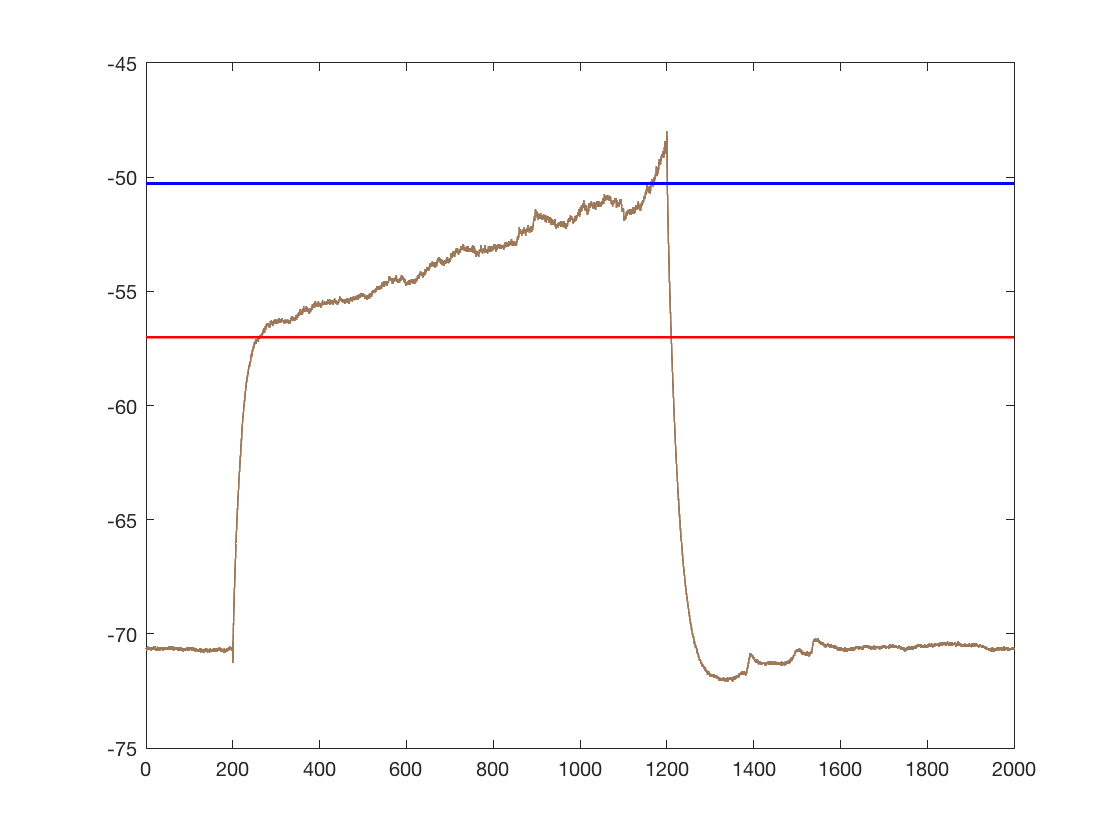

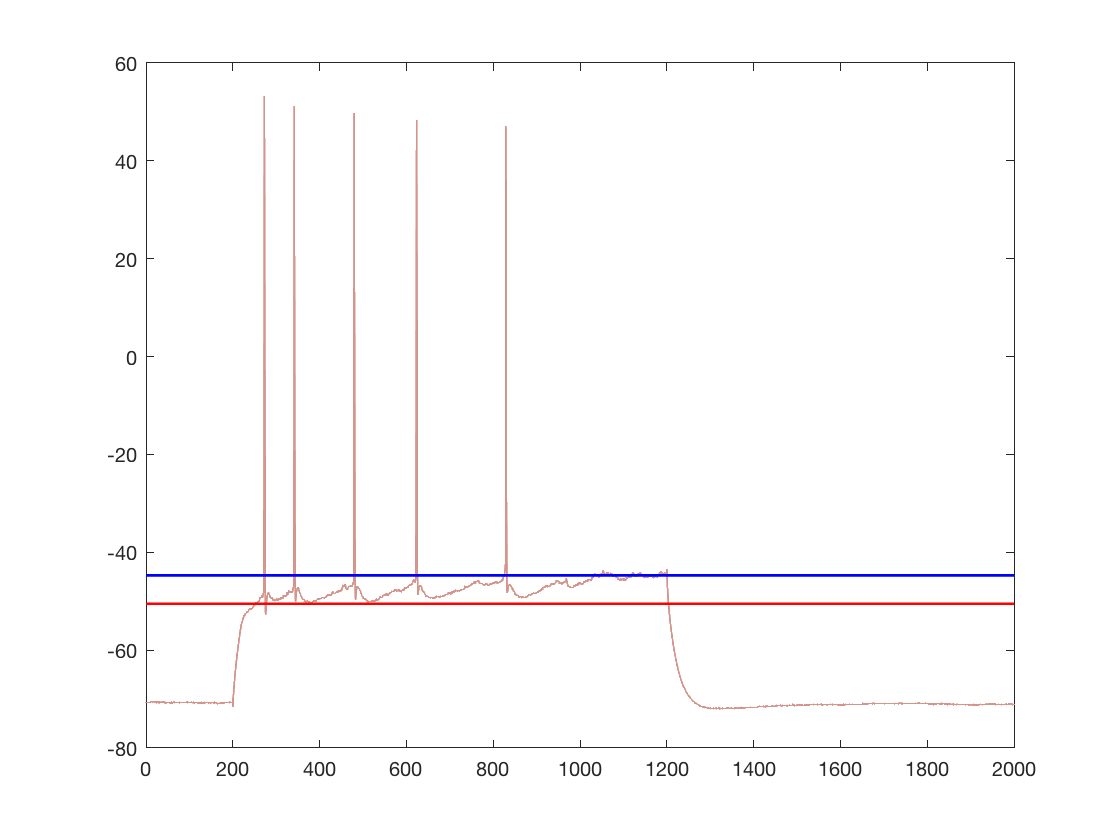

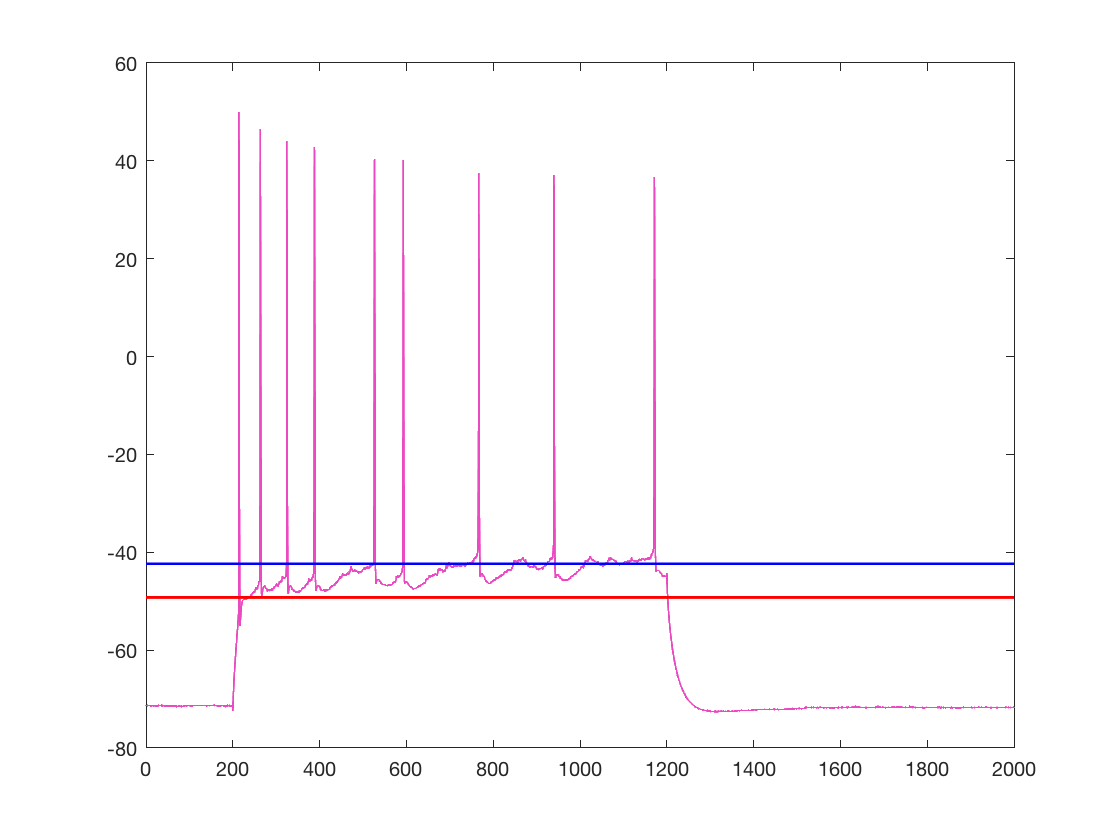

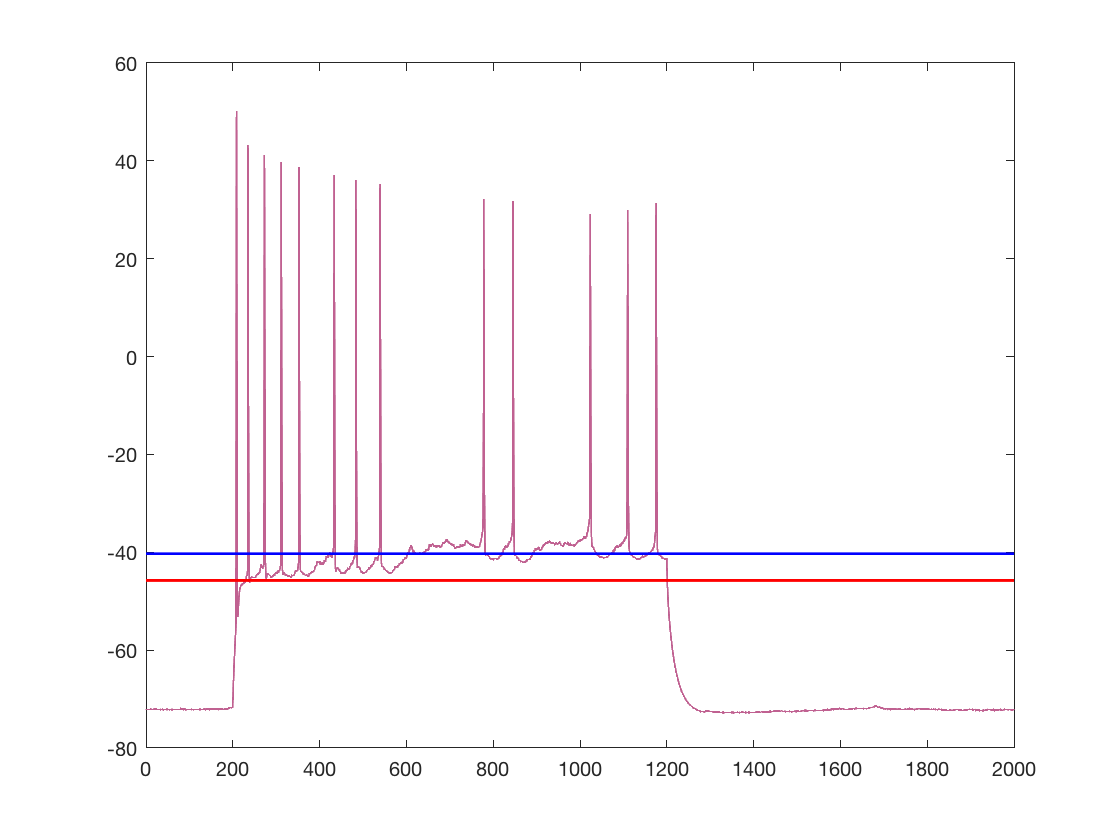


% figure showing the initial and final delta Vm for each sweep



for z = 1:2:10;
    figure;
    plot(t,in(z,:),'LineWidth',1,'color',[rand rand rand]);
    hold on;
    plot(t,Vstep_line_early(z,:),'LineWidth',1.5,'color',[1 0 0]);
    plot(t,Vstep_line_late(z,:),'LineWidth',1.5,'color',[0 0 1]);

end





% Superthreshold included, both positive and negative slow delta Vm            

%

slow_delta_Vm = zeros(10,1);
s = 1;
for s = 1:10;
    slow_delta_Vm(s) = y(s) - x(s);
    s = s+1;
end
clear s
 
slow_delta_Vm

slow_delta_Vm =    -0.2668
    0.2531
    6.7245
    4.6231
    5.8819
    7.2417
    6.8331
    5.8523
    5.4215
    9.6044



%




## Bin slow delta Vm values, sorting according to initial Vm reached (not delta Vm)

%


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% bin slow delta Vm values across 10 bins spanning the dynamic range of the depolarizing ramp 
% from 8 mV to 26 mV




alt_binned_Vstep_super_diff = NaN(10,200);



%{
ll
mm
nn
oo
pp
qq
rr
ss
tt
uu

%}
x

x =   -66.2577
  -61.4667
  -57.0013
  -53.1049
  -50.5641
  -49.9730
  -49.2264
  -47.5819
  -45.7447
  -44.3993


slow_delta_Vm

slow_delta_Vm =    -0.2668
    0.2531
    6.7245
    4.6231
    5.8819
    7.2417
    6.8331
    5.8523
    5.4215
    9.6044


%
            for zz = 1:10;
                if x(zz) < -68                   
                   
                   alt_binned_Vstep_super_diff(1,ll) = NaN;
                   alt_binned_Vstep_super_diff(2,mm) = NaN;
                   alt_binned_Vstep_super_diff(3,nn) = NaN;
                   alt_binned_Vstep_super_diff(4,oo) = NaN;
                   alt_binned_Vstep_super_diff(5,pp) = NaN;
                   alt_binned_Vstep_super_diff(6,qq) = NaN;
                   alt_binned_Vstep_super_diff(7,rr) = NaN;
                   alt_binned_Vstep_super_diff(8,ss) = NaN;
                   alt_binned_Vstep_super_diff(9,tt) = NaN;
                   alt_binned_Vstep_super_diff(10,uu) = NaN;
                   
                elseif x(zz) < -66
                    
                   alt_binned_Vstep_super_diff(1,ll) = slow_delta_Vm(zz);
                  
                   ll = ll+1;
                   
                   %alt_binned_Vstep_super_diff(1,ll) = NaN;
                   alt_binned_Vstep_super_diff(2,mm) = NaN;
                   alt_binned_Vstep_super_diff(3,nn) = NaN;
                   alt_binned_Vstep_super_diff(4,oo) = NaN;
                   alt_binned_Vstep_super_diff(5,pp) = NaN;
                   alt_binned_Vstep_super_diff(6,qq) = NaN;
                   alt_binned_Vstep_super_diff(7,rr) = NaN;
                   alt_binned_Vstep_super_diff(8,ss) = NaN;
                   alt_binned_Vstep_super_diff(9,tt) = NaN;
                   alt_binned_Vstep_super_diff(10,uu) = NaN;
            
                elseif x(zz) < -64
                  
                   alt_binned_Vstep_super_diff(2,mm) = slow_delta_Vm(zz);
                  
                   mm = mm+1;
                 
                   alt_binned_Vstep_super_diff(1,ll) = NaN;
                   %alt_binned_Vstep_super_diff(2,mm) = NaN;
                   alt_binned_Vstep_super_diff(3,nn) = NaN;
                   alt_binned_Vstep_super_diff(4,oo) = NaN;
                   alt_binned_Vstep_super_diff(5,pp) = NaN;
                   alt_binned_Vstep_super_diff(6,qq) = NaN;
                   alt_binned_Vstep_super_diff(7,rr) = NaN;
                   alt_binned_Vstep_super_diff(8,ss) = NaN;
                   alt_binned_Vstep_super_diff(9,tt) = NaN;
                   alt_binned_Vstep_super_diff(10,uu) = NaN;
                 
                                
                elseif x(zz) < -62     
                   alt_binned_Vstep_super_diff(3,nn) = slow_delta_Vm(zz);
                   nn = nn+1;
                   
                   alt_binned_Vstep_super_diff(1,ll) = NaN;
                   alt_binned_Vstep_super_diff(2,mm) = NaN;
                   %alt_binned_Vstep_super_diff(3,nn) = NaN;
                   alt_binned_Vstep_super_diff(4,oo) = NaN;
                   alt_binned_Vstep_super_diff(5,pp) = NaN;
                   alt_binned_Vstep_super_diff(6,qq) = NaN;
                   alt_binned_Vstep_super_diff(7,rr) = NaN;
                   alt_binned_Vstep_super_diff(8,ss) = NaN;
                   alt_binned_Vstep_super_diff(9,tt) = NaN;
                   alt_binned_Vstep_super_diff(10,uu) = NaN;
                 
                   
                elseif x(zz) < -60
                   
                   alt_binned_Vstep_super_diff(4,oo) = slow_delta_Vm(zz);
                   oo = oo+1;
                   
                   alt_binned_Vstep_super_diff(1,ll) = NaN;
                   alt_binned_Vstep_super_diff(2,mm) = NaN;
                   alt_binned_Vstep_super_diff(3,nn) = NaN;
                   %alt_binned_Vstep_super_diff(4,oo) = NaN;
                   alt_binned_Vstep_super_diff(5,pp) = NaN;
                   alt_binned_Vstep_super_diff(6,qq) = NaN;
                   alt_binned_Vstep_super_diff(7,rr) = NaN;
                   alt_binned_Vstep_super_diff(8,ss) = NaN;
                   alt_binned_Vstep_super_diff(9,tt) = NaN;
                   alt_binned_Vstep_super_diff(10,uu) = NaN;
                   
                elseif x(zz) < -58
               
                   alt_binned_Vstep_super_diff(5,pp) = slow_delta_Vm(zz);
                   pp = pp+1;
                   
                   alt_binned_Vstep_super_diff(1,ll) = NaN;
                   alt_binned_Vstep_super_diff(2,mm) = NaN;
                   alt_binned_Vstep_super_diff(3,nn) = NaN;
                   alt_binned_Vstep_super_diff(4,oo) = NaN;
                   %alt_binned_Vstep_super_diff(5,pp) = NaN;
                   alt_binned_Vstep_super_diff(6,qq) = NaN;
                   alt_binned_Vstep_super_diff(7,rr) = NaN;
                   alt_binned_Vstep_super_diff(8,ss) = NaN;
                   alt_binned_Vstep_super_diff(9,tt) = NaN;
                   alt_binned_Vstep_super_diff(10,uu) = NaN;
                   
            
                elseif x(zz) < -56
                   alt_binned_Vstep_super_diff(6,qq) = slow_delta_Vm(zz);
                   qq = qq+1;
                   
                   
                   alt_binned_Vstep_super_diff(1,ll) = NaN;
                   alt_binned_Vstep_super_diff(2,mm) = NaN;
                   alt_binned_Vstep_super_diff(3,nn) = NaN;
                   alt_binned_Vstep_super_diff(4,oo) = NaN;
                   alt_binned_Vstep_super_diff(5,pp) = NaN;
                   %alt_binned_Vstep_super_diff(6,qq) = NaN;
                   alt_binned_Vstep_super_diff(7,rr) = NaN;
                   alt_binned_Vstep_super_diff(8,ss) = NaN;
                   alt_binned_Vstep_super_diff(9,tt) = NaN;
                   alt_binned_Vstep_super_diff(10,uu) = NaN;
                   
                   
                elseif x(zz) < -54
                   alt_binned_Vstep_super_diff(7,rr) = slow_delta_Vm(zz);
                   rr = rr+1;
                 
                   alt_binned_Vstep_super_diff(1,ll) = NaN;
                   alt_binned_Vstep_super_diff(2,mm) = NaN;
                   alt_binned_Vstep_super_diff(3,nn) = NaN;
                   alt_binned_Vstep_super_diff(4,oo) = NaN;
                   alt_binned_Vstep_super_diff(5,pp) = NaN;
                   alt_binned_Vstep_super_diff(6,qq) = NaN;
                   %alt_binned_Vstep_super_diff(7,rr) = NaN;
                   alt_binned_Vstep_super_diff(8,ss) = NaN;
                   alt_binned_Vstep_super_diff(9,tt) = NaN;
                   alt_binned_Vstep_super_diff(10,uu) = NaN;
                   
                   
                elseif x(zz) < -52
                   
                   alt_binned_Vstep_super_diff(8,ss) = slow_delta_Vm(zz);
                   ss = ss+1;

                   
                   alt_binned_Vstep_super_diff(1,ll) = NaN;
                   alt_binned_Vstep_super_diff(2,mm) = NaN;
                   alt_binned_Vstep_super_diff(3,nn) = NaN;
                   alt_binned_Vstep_super_diff(4,oo) = NaN;
                   alt_binned_Vstep_super_diff(5,pp) = NaN;
                   alt_binned_Vstep_super_diff(6,qq) = NaN;
                   alt_binned_Vstep_super_diff(7,rr) = NaN;
                   %alt_binned_Vstep_super_diff(8,ss) = NaN;
                   alt_binned_Vstep_super_diff(9,tt) = NaN;
                   alt_binned_Vstep_super_diff(10,uu) = NaN;
                  
                elseif x(zz) < -50
             
                   alt_binned_Vstep_super_diff(9,tt) = slow_delta_Vm(zz);
                   tt = tt+1;
                  
                   
                   alt_binned_Vstep_super_diff(1,ll) = NaN;
                   alt_binned_Vstep_super_diff(2,mm) = NaN;
                   alt_binned_Vstep_super_diff(3,nn) = NaN;
                   alt_binned_Vstep_super_diff(4,oo) = NaN;
                   alt_binned_Vstep_super_diff(5,pp) = NaN;
                   alt_binned_Vstep_super_diff(6,qq) = NaN;
                   alt_binned_Vstep_super_diff(7,rr) = NaN;
                   alt_binned_Vstep_super_diff(8,ss) = NaN;
                   %alt_binned_Vstep_super_diff(9,tt) = NaN;
                   alt_binned_Vstep_super_diff(10,uu) = NaN;
                   
                elseif x(zz) < -48
                  
                   alt_binned_Vstep_super_diff(10,uu) = slow_delta_Vm(zz);
                   uu = uu+1;
              
                   alt_binned_Vstep_super_diff(1,ll) = NaN;
                   alt_binned_Vstep_super_diff(2,mm) = NaN;
                   alt_binned_Vstep_super_diff(3,nn) = NaN;
                   alt_binned_Vstep_super_diff(4,oo) = NaN;
                   alt_binned_Vstep_super_diff(5,pp) = NaN;
                   alt_binned_Vstep_super_diff(6,qq) = NaN;
                   alt_binned_Vstep_super_diff(7,rr) = NaN;
                   alt_binned_Vstep_super_diff(8,ss) = NaN;
                   alt_binned_Vstep_super_diff(9,tt) = NaN;
                   %alt_binned_Vstep_super_diff(10,uu) = NaN;
                  
                end
            end

       
     
%


## The slow delta Vm values are averaged for each cell, such that the n is equal to the number of cells (i.e. not counting multiple values at one level for one cell).

## collect into the  combined variable



binned_ramp_cell = nanmean(alt_binned_Vstep_super_diff,2);



if isnan(binned_ramp_cell(1)) == 1
    combined_binned_ramp(1,aaa) = NaN;
else
    combined_binned_ramp(1,aaa) = binned_ramp_cell(1);
    aaa = aaa +1;
end


if isnan(binned_ramp_cell(2)) == 1
    combined_binned_ramp(2,bbb) = NaN;
else
    combined_binned_ramp(2,bbb) = binned_ramp_cell(2);
    bbb = bbb +1;
end


if isnan(binned_ramp_cell(3)) == 1
    combined_binned_ramp(3,ccc) = NaN;
else
    combined_binned_ramp(3,ccc) = binned_ramp_cell(3);
    ccc = ccc +1;
end


if isnan(binned_ramp_cell(4)) == 1
    combined_binned_ramp(4,ddd) = NaN;
else
    combined_binned_ramp(4,ddd) = binned_ramp_cell(4);
    ddd = ddd +1;
end

if isnan(binned_ramp_cell(5)) == 1
    combined_binned_ramp(5,eee) = NaN;
else
    combined_binned_ramp(5,eee) = binned_ramp_cell(5);
    eee = eee +1;
end


if isnan(binned_ramp_cell(6)) == 1
    combined_binned_ramp(6,fff) = NaN;
else
    combined_binned_ramp(6,fff) = binned_ramp_cell(6);
    fff = fff +1;
end

if isnan(binned_ramp_cell(7)) == 1
    combined_binned_ramp(7,ggg) = NaN;
else
    combined_binned_ramp(7,ggg) = binned_ramp_cell(7);
    ggg = ggg +1;
end


if isnan(binned_ramp_cell(8)) == 1
    combined_binned_ramp(8,hhh) = NaN;
else
    combined_binned_ramp(8,hhh) = binned_ramp_cell(8);
    hhh = hhh +1;
end

if isnan(binned_ramp_cell(9)) == 1
    combined_binned_ramp(9,jjj) = NaN;
else
    combined_binned_ramp(9,jjj) = binned_ramp_cell(9);
    jjj = jjj +1;
end


if isnan(binned_ramp_cell(10)) == 1
    combined_binned_ramp(10,kkk) = NaN;
else
    combined_binned_ramp(10,kkk) = binned_ramp_cell(10);
    kkk = kkk +1;
end


alt_binned_Vstep_super_diff

alt_binned_Vstep_super_diff =    -0.2668       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       Na

binned_ramp_cell

binned_ramp_cell =    -0.2668
       NaN
       NaN
    0.2531
       NaN
    6.7245
       NaN
    4.6231
    5.8819
    7.0374


combined_binned_ramp

combined_binned_ramp =    -0.2668       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -0.3777       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN      



% want to count how many cells actually contribute to the combined binned
% data. So if all ten values of binned_ramp_cell are NaN, do nothing. If
% any of the ten values are non NaN, add to a counting variable. 


if isnan(binned_ramp_cell(1:10)) == 1
    nocount = nocount + 1;
else 
    count = count + 1;
    
end

count

count = 2

nocount

nocount = 0

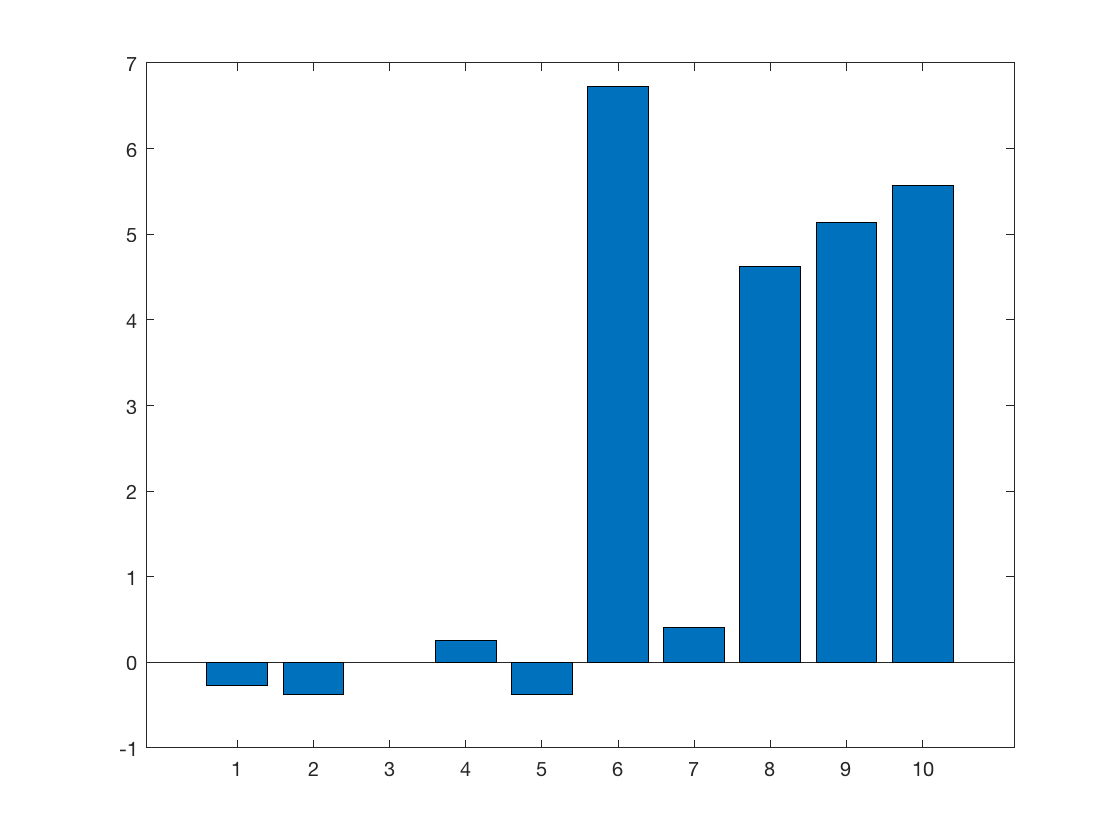


%clear alt_binned_Vstep_super_diff binned_ramp_cell

figure
bar(nanmean(combined_binned_ramp,2))